cd(fileparts(matlab.desktop.editor.getActiveFilename))
close all; clearvars; clc

cd("../data-engineering")
load("../../temp-data/participant_list.mat")
cd(fileparts(matlab.desktop.editor.getActiveFilename))

Compute TRMSE metric and make repeated measure tables.

y = [];
y_learning_effect = [];
y_learning_rate = [];
trials = [1:9]';
for i = 1:numel(participant_array)
    participant_handle = participant_array(i);
    fprintf("Participant %02d: %s\n", i, participant_handle.participant_id)
    cond_dict = participant_handle.cond_dict;
    cond_keys = keys(cond_dict);
    y_all_conds= [];
    y_learning_effect_all_conds = [];
    y_learning_rate_all_conds = [];
    for j = 1:numEntries(cond_dict)
        cond_label = cond_keys(j);
        fprintf("\tCondition: %s\n", cond_label)
        task_dict = cond_dict(cond_label).task_dict;
        task_keys = keys(task_dict);
        y_all_tasks = [];
        y_learning_effect_all_tasks = [];
        y_learning_rate_all_tasks = [];
        for k = 1:numEntries(task_dict)
            task_label = task_keys(k);
            fprintf("\t\tTask: %s\n", task_label)
            task_ttbl = task_dict{task_label}.data_ttbl;
            y_metric_all_trials = [];
            for t = 1:numel(trials)
                trial_label = sprintf("Trial %02d", t);
                trial_ttbl = extract_segment(task_ttbl, trial_label, task_label);
                trmse_coact = compute_gesture_metric(trial_ttbl, "trmse", "Co-Activation");
                trmse_diffact = compute_gesture_metric(trial_ttbl, "trmse", "Differentiation");
                fprintf("\t\t\t%s\tCo-Activation:%.3f\t Differentiation:%.3f\n", trial_label, trmse_coact, trmse_diffact)
                y_metric_all_trials = [y_metric_all_trials; [trmse_coact, trmse_diffact]];
            end
            y_task = compute_y_task(y_metric_all_trials, "exponential learning rate");
            y_all_tasks = [y_all_tasks, y_task];
            y_learning_effect_task = y_metric_all_trials(6:9,:) - y_metric_all_trials(1:4,:) %final - initial
            y_learning_effect_task = [y_learning_effect_task(:,1)', y_learning_effect_task(:,2)'] % coact x4 then diffact x4
            y_learning_effect_all_tasks = [y_learning_effect_all_tasks, y_learning_effect_task];
            for l=1:size(y_metric_all_trials,2)
                exp_model{l} = fit(trials, y_metric_all_trials(:, l), 'exp1', 'StartPoint', [0.6, -0.2]); % Initial guess from x=1,9;y = 0.5,0.1
                exp_coeffs(l,:) = coeffvalues(exp_model{l})
            end
            y_learning_rate_task = [exp_coeffs(1,2), exp_coeffs(2,2)]
            y_learning_rate_all_tasks = [y_learning_rate_all_tasks, y_learning_rate_task];
        end
        y_cond = [table(cond_label, 'VariableNames', "b_condition"), array2table(y_all_tasks, "VariableNames",arrayfun(@(x) sprintf("y_%d", x), 1:size(y_all_tasks, 2)))];
        y_all_conds = [y_all_conds; y_cond];
        y_learning_effect_cond = [table(cond_label, 'VariableNames', "b_condition"), array2table(y_learning_effect_all_tasks, "VariableNames",arrayfun(@(x) sprintf("y_learning_effect_%d", x), 1:size(y_learning_effect_all_tasks, 2)))];
        y_learning_effect_all_conds = [y_learning_effect_all_conds; y_learning_effect_cond];
        y_learning_rate_cond = [table(cond_label, 'VariableNames', "b_condition"), array2table(y_learning_rate_all_tasks, "VariableNames",arrayfun(@(x) sprintf("y_learning_rate_%d", x), 1:size(y_learning_rate_all_tasks, 2)))];
        y_learning_rate_all_conds = [y_learning_rate_all_conds; y_learning_rate_cond];
    end
    y = [y; y_all_conds];
    y_learning_effect = [y_learning_effect; y_learning_effect_all_conds];
    y_learning_rate = [y_learning_rate; y_learning_rate_all_conds];
end

Participant 01: P05


	Condition: par


		Task: ml


			Trial 01	Co-Activation:0.429	 Differentiation:0.144
			Trial 02	Co-Activation:0.470	 Differentiation:0.252
			Trial 03	Co-Activation:0.470	 Differentiation:0.287
			Trial 04	Co-Activation:0.417	 Differentiation:0.329
			Trial 05	Co-Activation:0.418	 Differentiation:0.315
			Trial 06	Co-Activation:0.457	 Differentiation:0.172
			Trial 07	Co-Activation:0.394	 Differentiation:0.231
			Trial 08	Co-Activation:0.385	 Differentiation:0.147
			Trial 09	Co-Activation:0.343	 Differentiation:0.285


y_learning_effect_task =     0.0284    0.0288
   -0.0756   -0.0217
   -0.0852   -0.1401
   -0.0748   -0.0434


y_learning_effect_task =     0.0284   -0.0756   -0.0852   -0.0748    0.0288   -0.0217   -0.1401   -0.0434


exp_coeffs =     0.4805   -0.0273
    0.1139   -0.0134


exp_coeffs =     0.4805   -0.0273
    0.2417   -0.0012


y_learning_rate_task =    -0.0273   -0.0012


		Task: hl


			Trial 01	Co-Activation:0.444	 Differentiation:0.110
			Trial 02	Co-Activation:0.322	 Differentiation:0.112
			Trial 03	Co-Activation:0.319	 Differentiation:0.144
			Trial 04	Co-Activation:0.245	 Differentiation:0.120
			Trial 05	Co-Activation:0.246	 Differentiation:0.179
			Trial 06	Co-Activation:0.274	 Differentiation:0.045
			Trial 07	Co-Activation:0.273	 Differentiation:0.057
			Trial 08	Co-Activation:0.380	 Differentiation:0.140
			Trial 09	Co-Activation:0.401	 Differentiation:0.116


y_learning_effect_task =    -0.1704   -0.0650
   -0.0494   -0.0550
    0.0609   -0.0036
    0.1557   -0.0039


y_learning_effect_task =    -0.1704   -0.0494    0.0609    0.1557   -0.0650   -0.0550   -0.0036   -0.0039


exp_coeffs =     0.3292   -0.0040
    0.2417   -0.0012


exp_coeffs =     0.3292   -0.0040
    0.1256   -0.0204


y_learning_rate_task =    -0.0040   -0.0204


		Task: cl


			Trial 01	Co-Activation:0.348	 Differentiation:0.116
			Trial 02	Co-Activation:0.281	 Differentiation:0.223
			Trial 03	Co-Activation:0.467	 Differentiation:0.195
			Trial 04	Co-Activation:0.322	 Differentiation:0.117
			Trial 05	Co-Activation:0.237	 Differentiation:0.269
			Trial 06	Co-Activation:0.270	 Differentiation:0.065
			Trial 07	Co-Activation:0.324	 Differentiation:0.112
			Trial 08	Co-Activation:0.256	 Differentiation:0.114
			Trial 09	Co-Activation:0.390	 Differentiation:0.103


y_learning_effect_task =    -0.0777   -0.0511
    0.0422   -0.1113
   -0.2108   -0.0808
    0.0684   -0.0134


y_learning_effect_task =    -0.0777    0.0422   -0.2108    0.0684   -0.0511   -0.1113   -0.0808   -0.0134


exp_coeffs =     0.3437   -0.0134
    0.1256   -0.0204


exp_coeffs =     0.3437   -0.0134
    0.1962   -0.0614


y_learning_rate_task =    -0.0134   -0.0614


	Condition: xpar


		Task: ml


			Trial 01	Co-Activation:0.351	 Differentiation:0.218
			Trial 02	Co-Activation:0.329	 Differentiation:0.049
			Trial 03	Co-Activation:0.351	 Differentiation:0.173
			Trial 04	Co-Activation:0.338	 Differentiation:0.108
			Trial 05	Co-Activation:0.363	 Differentiation:0.135
			Trial 06	Co-Activation:0.334	 Differentiation:0.138
			Trial 07	Co-Activation:0.356	 Differentiation:0.157
			Trial 08	Co-Activation:0.439	 Differentiation:0.234
			Trial 09	Co-Activation:0.405	 Differentiation:0.228


y_learning_effect_task =    -0.0165   -0.0797
    0.0276    0.1081
    0.0881    0.0602
    0.0667    0.1205


y_learning_effect_task =    -0.0165    0.0276    0.0881    0.0667   -0.0797    0.1081    0.0602    0.1205


exp_coeffs =     0.3173    0.0263
    0.1962   -0.0614


exp_coeffs =     0.3173    0.0263
    0.1083    0.0738


y_learning_rate_task =     0.0263    0.0738


		Task: hl


			Trial 01	Co-Activation:0.189	 Differentiation:0.383
			Trial 02	Co-Activation:0.232	 Differentiation:0.288
			Trial 03	Co-Activation:0.202	 Differentiation:0.342
			Trial 04	Co-Activation:0.264	 Differentiation:0.445
			Trial 05	Co-Activation:0.248	 Differentiation:0.277
			Trial 06	Co-Activation:0.271	 Differentiation:0.292
			Trial 07	Co-Activation:0.253	 Differentiation:0.132
			Trial 08	Co-Activation:0.274	 Differentiation:0.208
			Trial 09	Co-Activation:0.213	 Differentiation:0.402


y_learning_effect_task =     0.0815   -0.0915
    0.0208   -0.1565
    0.0719   -0.1336
   -0.0514   -0.0430


y_learning_effect_task =     0.0815    0.0208    0.0719   -0.0514   -0.0915   -0.1565   -0.1336   -0.0430


exp_coeffs =     0.2138    0.0215
    0.1083    0.0738


exp_coeffs =     0.2138    0.0215
    0.3780   -0.0425


y_learning_rate_task =     0.0215   -0.0425


		Task: cl


			Trial 01	Co-Activation:0.231	 Differentiation:0.333
			Trial 02	Co-Activation:0.362	 Differentiation:0.100
			Trial 03	Co-Activation:0.237	 Differentiation:0.180
			Trial 04	Co-Activation:0.304	 Differentiation:0.131
			Trial 05	Co-Activation:0.196	 Differentiation:0.102
			Trial 06	Co-Activation:0.255	 Differentiation:0.117
			Trial 07	Co-Activation:0.217	 Differentiation:0.108
			Trial 08	Co-Activation:0.248	 Differentiation:0.135
			Trial 09	Co-Activation:0.223	 Differentiation:0.098


y_learning_effect_task =     0.0243   -0.2156
   -0.1450    0.0081
    0.0110   -0.0449
   -0.0816   -0.0322


y_learning_effect_task =     0.0243   -0.1450    0.0110   -0.0816   -0.2156    0.0081   -0.0449   -0.0322


exp_coeffs =     0.2930   -0.0304
    0.3780   -0.0425


exp_coeffs =     0.2930   -0.0304
    0.2753   -0.1448


y_learning_rate_task =    -0.0304   -0.1448


Participant 02: P06


	Condition: par


		Task: ml


			Trial 01	Co-Activation:0.477	 Differentiation:0.220
			Trial 02	Co-Activation:0.292	 Differentiation:0.170
			Trial 03	Co-Activation:0.316	 Differentiation:0.168
			Trial 04	Co-Activation:0.495	 Differentiation:0.501
			Trial 05	Co-Activation:0.742	 Differentiation:0.527
			Trial 06	Co-Activation:0.670	 Differentiation:0.433
			Trial 07	Co-Activation:0.525	 Differentiation:0.252
			Trial 08	Co-Activation:0.396	 Differentiation:0.249
			Trial 09	Co-Activation:0.402	 Differentiation:0.200


y_learning_effect_task =     0.1934    0.2129
    0.2331    0.0825
    0.0805    0.0815
   -0.0929   -0.3005


y_learning_effect_task =     0.1934    0.2331    0.0805   -0.0929    0.2129    0.0825    0.0815   -0.3005


exp_coeffs =     0.4367    0.0185
    0.2753   -0.1448


exp_coeffs =     0.4367    0.0185
    0.2855    0.0113


y_learning_rate_task =     0.0185    0.0113


		Task: hl


			Trial 01	Co-Activation:0.451	 Differentiation:0.200
			Trial 02	Co-Activation:0.415	 Differentiation:0.156
			Trial 03	Co-Activation:0.436	 Differentiation:0.308
			Trial 04	Co-Activation:0.422	 Differentiation:0.273
			Trial 05	Co-Activation:0.445	 Differentiation:0.626
			Trial 06	Co-Activation:0.418	 Differentiation:0.620
			Trial 07	Co-Activation:0.388	 Differentiation:0.609
			Trial 08	Co-Activation:0.425	 Differentiation:0.237
			Trial 09	Co-Activation:0.306	 Differentiation:0.659


y_learning_effect_task =    -0.0333    0.4199
   -0.0272    0.4522
   -0.0111   -0.0710
   -0.1158    0.3861


y_learning_effect_task =    -0.0333   -0.0272   -0.0111   -0.1158    0.4199    0.4522   -0.0710    0.3861


exp_coeffs =     0.4668   -0.0254
    0.2855    0.0113


exp_coeffs =     0.4668   -0.0254
    0.2301    0.1087


y_learning_rate_task =    -0.0254    0.1087


		Task: cl


			Trial 01	Co-Activation:0.374	 Differentiation:0.646
			Trial 02	Co-Activation:0.347	 Differentiation:0.271
			Trial 03	Co-Activation:0.366	 Differentiation:0.262
			Trial 04	Co-Activation:0.282	 Differentiation:0.149
			Trial 05	Co-Activation:0.252	 Differentiation:0.237
			Trial 06	Co-Activation:0.333	 Differentiation:0.060
			Trial 07	Co-Activation:0.365	 Differentiation:0.398
			Trial 08	Co-Activation:0.277	 Differentiation:0.159
			Trial 09	Co-Activation:0.356	 Differentiation:0.088


y_learning_effect_task =    -0.0406   -0.5858
    0.0183    0.1267
   -0.0884   -0.1031
    0.0738   -0.0610


y_learning_effect_task =    -0.0406    0.0183   -0.0884    0.0738   -0.5858    0.1267   -0.1031   -0.0610


exp_coeffs =     0.3488   -0.0125
    0.2301    0.1087


exp_coeffs =     0.3488   -0.0125
    0.6169   -0.2150


y_learning_rate_task =    -0.0125   -0.2150


	Condition: xpar


		Task: ml


			Trial 01	Co-Activation:0.565	 Differentiation:0.329
			Trial 02	Co-Activation:0.489	 Differentiation:0.742
			Trial 03	Co-Activation:0.488	 Differentiation:0.702
			Trial 04	Co-Activation:0.479	 Differentiation:0.715
			Trial 05	Co-Activation:0.490	 Differentiation:0.742
			Trial 06	Co-Activation:0.490	 Differentiation:0.741
			Trial 07	Co-Activation:0.490	 Differentiation:0.740
			Trial 08	Co-Activation:0.439	 Differentiation:0.683
			Trial 09	Co-Activation:0.172	 Differentiation:0.212


y_learning_effect_task =    -0.0755    0.4118
    0.0009   -0.0024
   -0.0496   -0.0187
   -0.3072   -0.5028


y_learning_effect_task =    -0.0755    0.0009   -0.0496   -0.3072    0.4118   -0.0024   -0.0187   -0.5028


exp_coeffs =     0.6023   -0.0578
    0.6169   -0.2150


exp_coeffs =     0.6023   -0.0578
    0.6604   -0.0118


y_learning_rate_task =    -0.0578   -0.0118


		Task: hl


			Trial 01	Co-Activation:0.349	 Differentiation:0.219
			Trial 02	Co-Activation:0.388	 Differentiation:0.239
			Trial 03	Co-Activation:0.437	 Differentiation:0.232
			Trial 04	Co-Activation:0.384	 Differentiation:0.224
			Trial 05	Co-Activation:0.439	 Differentiation:0.296
			Trial 06	Co-Activation:0.416	 Differentiation:0.226
			Trial 07	Co-Activation:0.429	 Differentiation:0.216
			Trial 08	Co-Activation:0.432	 Differentiation:0.174
			Trial 09	Co-Activation:0.433	 Differentiation:0.180


y_learning_effect_task = 4×2
    0.0667    0.0072
    0.0412   -0.0224
   -0.0045   -0.0574
    0.0489   -0.0441


y_learning_effect_task = 1×8
    0.0667    0.0412   -0.0045    0.0489    0.0072   -0.0224   -0.0574   -0.0441


exp_coeffs = 2×2
    0.3739    0.0191
    0.6604   -0.0118


exp_coeffs = 2×2
    0.3739    0.0191
    0.2536   -0.0262


y_learning_rate_task = 1×2
    0.0191   -0.0262


		Task: cl


			Trial 01	Co-Activation:0.428	 Differentiation:0.223
			Trial 02	Co-Activation:0.384	 Differentiation:0.198
			Trial 03	Co-Activation:0.344	 Differentiation:0.203
			Trial 04	Co-Activation:0.181	 Differentiation:0.202
			Trial 05	Co-Activation:0.426	 Differentiation:0.240
			Trial 06	Co-Activation:0.324	 Differentiation:0.045
			Trial 07	Co-Activation:0.398	 Differentiation:0.229
			Trial 08	Co-Activation:0.265	 Differentiation:0.143
			Trial 09	Co-Activation:0.204	 Differentiation:0.091


y_learning_effect_task = 4×2
   -0.1040   -0.1776
    0.0145    0.0311
   -0.0796   -0.0603
    0.0231   -0.1106


y_learning_effect_task = 1×8
   -0.1040    0.0145   -0.0796    0.0231   -0.1776    0.0311   -0.0603   -0.1106


exp_coeffs = 2×2
    0.4187   -0.0504
    0.2536   -0.0262


exp_coeffs = 2×2
    0.4187   -0.0504
    0.2472   -0.0726


y_learning_rate_task = 1×2
   -0.0504   -0.0726


Participant 03: P07


	Condition: par


		Task: ml


			Trial 01	Co-Activation:0.698	 Differentiation:0.535
			Trial 02	Co-Activation:0.745	 Differentiation:0.784
			Trial 03	Co-Activation:0.448	 Differentiation:0.343
			Trial 04	Co-Activation:0.353	 Differentiation:0.121
			Trial 05	Co-Activation:0.490	 Differentiation:0.242
			Trial 06	Co-Activation:0.571	 Differentiation:0.371
			Trial 07	Co-Activation:0.435	 Differentiation:0.151
			Trial 08	Co-Activation:0.389	 Differentiation:0.122
			Trial 09	Co-Activation:0.359	 Differentiation:0.107


y_learning_effect_task = 4×2
   -0.1277   -0.1643
   -0.3093   -0.6327
   -0.0589   -0.2211
    0.0062   -0.0130


y_learning_effect_task = 1×8
   -0.1277   -0.3093   -0.0589    0.0062   -0.1643   -0.6327   -0.2211   -0.0130


exp_coeffs = 2×2
    0.7241   -0.0790
    0.2472   -0.0726


exp_coeffs = 2×2
    0.7241   -0.0790
    0.8014   -0.2234


y_learning_rate_task = 1×2
   -0.0790   -0.2234


		Task: hl


			Trial 01	Co-Activation:0.452	 Differentiation:0.260
			Trial 02	Co-Activation:0.478	 Differentiation:0.323
			Trial 03	Co-Activation:0.475	 Differentiation:0.197
			Trial 04	Co-Activation:0.450	 Differentiation:0.235
			Trial 05	Co-Activation:0.455	 Differentiation:0.215
			Trial 06	Co-Activation:0.490	 Differentiation:0.315
			Trial 07	Co-Activation:0.487	 Differentiation:0.572
			Trial 08	Co-Activation:0.490	 Differentiation:0.623
			Trial 09	Co-Activation:0.482	 Differentiation:0.245


y_learning_effect_task = 4×2
    0.0381    0.0552
    0.0094    0.2492
    0.0149    0.4259
    0.0322    0.0094


y_learning_effect_task = 1×8
    0.0381    0.0094    0.0149    0.0322    0.0552    0.2492    0.4259    0.0094


exp_coeffs = 2×2
    0.4549    0.0078
    0.8014   -0.2234


exp_coeffs = 2×2
    0.4549    0.0078
    0.2146    0.0827


y_learning_rate_task = 1×2
    0.0078    0.0827


		Task: cl


			Trial 01	Co-Activation:0.469	 Differentiation:0.696
			Trial 02	Co-Activation:0.469	 Differentiation:0.164
			Trial 03	Co-Activation:0.447	 Differentiation:0.163
			Trial 04	Co-Activation:0.485	 Differentiation:0.245
			Trial 05	Co-Activation:0.489	 Differentiation:0.221
			Trial 06	Co-Activation:0.315	 Differentiation:0.198
			Trial 07	Co-Activation:0.407	 Differentiation:0.278
			Trial 08	Co-Activation:0.304	 Differentiation:0.279
			Trial 09	Co-Activation:0.327	 Differentiation:0.123


y_learning_effect_task = 4×2
   -0.1543   -0.4976
   -0.0618    0.1141
   -0.1434    0.1162
   -0.1581   -0.1215


y_learning_effect_task = 1×8
   -0.1543   -0.0618   -0.1434   -0.1581   -0.4976    0.1141    0.1162   -0.1215


exp_coeffs = 2×2
    0.5282   -0.0511
    0.2146    0.0827


exp_coeffs = 2×2
    0.5282   -0.0511
    0.5160   -0.1543


y_learning_rate_task = 1×2
   -0.0511   -0.1543


	Condition: xpar


		Task: ml


			Trial 01	Co-Activation:0.603	 Differentiation:0.278
			Trial 02	Co-Activation:0.480	 Differentiation:0.500
			Trial 03	Co-Activation:0.380	 Differentiation:0.501
			Trial 04	Co-Activation:0.256	 Differentiation:0.407
			Trial 05	Co-Activation:0.321	 Differentiation:0.252
			Trial 06	Co-Activation:0.332	 Differentiation:0.321
			Trial 07	Co-Activation:0.214	 Differentiation:0.251
			Trial 08	Co-Activation:0.113	 Differentiation:0.145
			Trial 09	Co-Activation:0.084	 Differentiation:0.165


y_learning_effect_task = 4×2
   -0.2707    0.0423
   -0.2666   -0.2487
   -0.2670   -0.3562
   -0.1719   -0.2427


y_learning_effect_task = 1×8
   -0.2707   -0.2666   -0.2670   -0.1719    0.0423   -0.2487   -0.3562   -0.2427


exp_coeffs = 2×2
    0.7071   -0.1879
    0.5160   -0.1543


exp_coeffs = 2×2
    0.7071   -0.1879
    0.4970   -0.0975


y_learning_rate_task = 1×2
   -0.1879   -0.0975


		Task: hl


			Trial 01	Co-Activation:0.444	 Differentiation:0.182
			Trial 02	Co-Activation:0.361	 Differentiation:0.142
			Trial 03	Co-Activation:0.337	 Differentiation:0.131
			Trial 04	Co-Activation:0.431	 Differentiation:0.080
			Trial 05	Co-Activation:0.423	 Differentiation:0.194
			Trial 06	Co-Activation:0.444	 Differentiation:0.196
			Trial 07	Co-Activation:0.332	 Differentiation:0.175
			Trial 08	Co-Activation:0.417	 Differentiation:0.489
			Trial 09	Co-Activation:0.422	 Differentiation:0.204


y_learning_effect_task = 4×2
    0.0001    0.0145
   -0.0299    0.0326
    0.0797    0.3589
   -0.0095    0.1242


y_learning_effect_task = 1×8
    0.0001   -0.0299    0.0797   -0.0095    0.0145    0.0326    0.3589    0.1242


exp_coeffs = 2×2
    0.3945    0.0033
    0.4970   -0.0975


exp_coeffs = 2×2
    0.3945    0.0033
    0.1034    0.1212


y_learning_rate_task = 1×2
    0.0033    0.1212


		Task: cl


			Trial 01	Co-Activation:0.454	 Differentiation:0.229
			Trial 02	Co-Activation:0.420	 Differentiation:0.193
			Trial 03	Co-Activation:0.344	 Differentiation:0.154
			Trial 04	Co-Activation:0.471	 Differentiation:0.162
			Trial 05	Co-Activation:0.392	 Differentiation:0.170
			Trial 06	Co-Activation:0.379	 Differentiation:0.222
			Trial 07	Co-Activation:0.279	 Differentiation:0.135
			Trial 08	Co-Activation:0.255	 Differentiation:0.106
			Trial 09	Co-Activation:0.291	 Differentiation:0.127


y_learning_effect_task = 4×2
   -0.0743   -0.0068
   -0.1411   -0.0587
   -0.0889   -0.0478
   -0.1806   -0.0343


y_learning_effect_task = 1×8
   -0.0743   -0.1411   -0.0889   -0.1806   -0.0068   -0.0587   -0.0478   -0.0343


exp_coeffs = 2×2
    0.4883   -0.0606
    0.1034    0.1212


exp_coeffs = 2×2
    0.4883   -0.0606
    0.2267   -0.0643


y_learning_rate_task = 1×2
   -0.0606   -0.0643


Participant 04: P08


	Condition: par


		Task: ml


			Trial 01	Co-Activation:0.432	 Differentiation:0.476
			Trial 02	Co-Activation:0.469	 Differentiation:0.266
			Trial 03	Co-Activation:0.405	 Differentiation:0.245
			Trial 04	Co-Activation:0.373	 Differentiation:0.276
			Trial 05	Co-Activation:0.386	 Differentiation:0.244
			Trial 06	Co-Activation:0.333	 Differentiation:0.439
			Trial 07	Co-Activation:0.392	 Differentiation:0.237
			Trial 08	Co-Activation:0.341	 Differentiation:0.257
			Trial 09	Co-Activation:0.458	 Differentiation:0.264


y_learning_effect_task = 4×2
   -0.0994   -0.0364
   -0.0762   -0.0296
   -0.0637    0.0120
    0.0851   -0.0116


y_learning_effect_task = 1×8
   -0.0994   -0.0762   -0.0637    0.0851   -0.0364   -0.0296    0.0120   -0.0116


exp_coeffs = 2×2
    0.4303   -0.0153
    0.2267   -0.0643


exp_coeffs = 2×2
    0.4303   -0.0153
    0.3705   -0.0433


y_learning_rate_task = 1×2
   -0.0153   -0.0433


		Task: hl


			Trial 01	Co-Activation:0.436	 Differentiation:0.695
			Trial 02	Co-Activation:0.399	 Differentiation:0.646
			Trial 03	Co-Activation:0.382	 Differentiation:0.524
			Trial 04	Co-Activation:0.399	 Differentiation:0.672
			Trial 05	Co-Activation:0.384	 Differentiation:0.616
			Trial 06	Co-Activation:0.309	 Differentiation:0.533
			Trial 07	Co-Activation:0.318	 Differentiation:0.599
			Trial 08	Co-Activation:0.300	 Differentiation:0.673
			Trial 09	Co-Activation:0.385	 Differentiation:0.677


y_learning_effect_task = 4×2
   -0.1270   -0.1627
   -0.0815   -0.0469
   -0.0822    0.1483
   -0.0136    0.0051


y_learning_effect_task = 1×8
   -0.1270   -0.0815   -0.0822   -0.0136   -0.1627   -0.0469    0.1483    0.0051


exp_coeffs = 2×2
    0.4341   -0.0338
    0.3705   -0.0433


exp_coeffs = 2×2
    0.4341   -0.0338
    0.6247    0.0005


y_learning_rate_task = 1×2
   -0.0338    0.0005


		Task: cl


			Trial 01	Co-Activation:0.482	 Differentiation:0.209
			Trial 02	Co-Activation:0.430	 Differentiation:0.195
			Trial 03	Co-Activation:0.251	 Differentiation:0.243
			Trial 04	Co-Activation:0.396	 Differentiation:0.142
			Trial 05	Co-Activation:0.302	 Differentiation:0.151
			Trial 06	Co-Activation:0.332	 Differentiation:0.112
			Trial 07	Co-Activation:0.196	 Differentiation:0.140
			Trial 08	Co-Activation:0.317	 Differentiation:0.124
			Trial 09	Co-Activation:0.320	 Differentiation:0.219


y_learning_effect_task = 4×2
   -0.1494   -0.0973
   -0.2341   -0.0551
    0.0663   -0.1185
   -0.0760    0.0768


y_learning_effect_task = 1×8
   -0.1494   -0.2341    0.0663   -0.0760   -0.0973   -0.0551   -0.1185    0.0768


exp_coeffs = 2×2
    0.4548   -0.0633
    0.6247    0.0005


exp_coeffs = 2×2
    0.4548   -0.0633
    0.2123   -0.0452


y_learning_rate_task = 1×2
   -0.0633   -0.0452


	Condition: xpar


		Task: ml


			Trial 01	Co-Activation:0.243	 Differentiation:0.337
			Trial 02	Co-Activation:0.354	 Differentiation:0.327
			Trial 03	Co-Activation:0.494	 Differentiation:0.304
			Trial 04	Co-Activation:0.427	 Differentiation:0.290
			Trial 05	Co-Activation:0.441	 Differentiation:0.273
			Trial 06	Co-Activation:0.453	 Differentiation:0.245
			Trial 07	Co-Activation:0.440	 Differentiation:0.279
			Trial 08	Co-Activation:0.373	 Differentiation:0.257
			Trial 09	Co-Activation:0.487	 Differentiation:0.234


y_learning_effect_task = 4×2
    0.2098   -0.0921
    0.0859   -0.0478
   -0.1203   -0.0463
    0.0608   -0.0563


y_learning_effect_task = 1×8
    0.2098    0.0859   -0.1203    0.0608   -0.0921   -0.0478   -0.0463   -0.0563


exp_coeffs = 2×2
    0.3434    0.0358
    0.2123   -0.0452


exp_coeffs = 2×2
    0.3434    0.0358
    0.3483   -0.0429


y_learning_rate_task = 1×2
    0.0358   -0.0429


		Task: hl


			Trial 01	Co-Activation:0.386	 Differentiation:0.146
			Trial 02	Co-Activation:0.238	 Differentiation:0.176
			Trial 03	Co-Activation:0.306	 Differentiation:0.574
			Trial 04	Co-Activation:0.365	 Differentiation:0.540
			Trial 05	Co-Activation:0.205	 Differentiation:0.210
			Trial 06	Co-Activation:0.242	 Differentiation:0.107
			Trial 07	Co-Activation:0.317	 Differentiation:0.367
			Trial 08	Co-Activation:0.340	 Differentiation:0.248
			Trial 09	Co-Activation:0.401	 Differentiation:0.283


y_learning_effect_task = 4×2
   -0.1444   -0.0393
    0.0798    0.1907
    0.0333   -0.3259
    0.0365   -0.2561


y_learning_effect_task = 1×8
   -0.1444    0.0798    0.0333    0.0365   -0.0393    0.1907   -0.3259   -0.2561


exp_coeffs = 2×2
    0.2869    0.0161
    0.3483   -0.0429


exp_coeffs = 2×2
    0.2869    0.0161
    0.3005   -0.0040


y_learning_rate_task = 1×2
    0.0161   -0.0040


		Task: cl


			Trial 01	Co-Activation:0.356	 Differentiation:0.153
			Trial 02	Co-Activation:0.367	 Differentiation:0.138
			Trial 03	Co-Activation:0.415	 Differentiation:0.237
			Trial 04	Co-Activation:0.320	 Differentiation:0.121
			Trial 05	Co-Activation:0.376	 Differentiation:0.467
			Trial 06	Co-Activation:0.265	 Differentiation:0.139
			Trial 07	Co-Activation:0.235	 Differentiation:0.105
			Trial 08	Co-Activation:0.298	 Differentiation:0.201
			Trial 09	Co-Activation:0.364	 Differentiation:0.182


y_learning_effect_task = 4×2
   -0.0916   -0.0133
   -0.1319   -0.0333
   -0.1172   -0.0358
    0.0436    0.0611


y_learning_effect_task = 1×8
   -0.0916   -0.1319   -0.1172    0.0436   -0.0133   -0.0333   -0.0358    0.0611


exp_coeffs = 2×2
    0.3868   -0.0306
    0.3005   -0.0040


exp_coeffs = 2×2
    0.3868   -0.0306
    0.1893    0.0045


y_learning_rate_task = 1×2
   -0.0306    0.0045


Participant 05: P09


	Condition: par


		Task: ml


			Trial 01	Co-Activation:0.490	 Differentiation:0.220
			Trial 02	Co-Activation:0.438	 Differentiation:0.171
			Trial 03	Co-Activation:0.381	 Differentiation:0.142
			Trial 04	Co-Activation:0.386	 Differentiation:0.136
			Trial 05	Co-Activation:0.376	 Differentiation:0.134
			Trial 06	Co-Activation:0.383	 Differentiation:0.144
			Trial 07	Co-Activation:0.400	 Differentiation:0.139
			Trial 08	Co-Activation:0.365	 Differentiation:0.139
			Trial 09	Co-Activation:0.381	 Differentiation:0.127


y_learning_effect_task = 4×2
   -0.1070   -0.0753
   -0.0387   -0.0317
   -0.0161   -0.0027
   -0.0047   -0.0091


y_learning_effect_task = 1×8
   -0.1070   -0.0387   -0.0161   -0.0047   -0.0753   -0.0317   -0.0027   -0.0091


exp_coeffs = 2×2
    0.4566   -0.0270
    0.1893    0.0045


exp_coeffs = 2×2
    0.4566   -0.0270
    0.1963   -0.0558


y_learning_rate_task = 1×2
   -0.0270   -0.0558


		Task: hl


			Trial 01	Co-Activation:0.305	 Differentiation:0.286
			Trial 02	Co-Activation:0.317	 Differentiation:0.299
			Trial 03	Co-Activation:0.391	 Differentiation:0.271
			Trial 04	Co-Activation:0.377	 Differentiation:0.247
			Trial 05	Co-Activation:0.436	 Differentiation:0.295
			Trial 06	Co-Activation:0.418	 Differentiation:0.378
			Trial 07	Co-Activation:0.380	 Differentiation:0.423
			Trial 08	Co-Activation:0.400	 Differentiation:0.322
			Trial 09	Co-Activation:0.374	 Differentiation:0.560


y_learning_effect_task = 4×2
    0.1121    0.0923
    0.0626    0.1241
    0.0094    0.0506
   -0.0026    0.3133


y_learning_effect_task = 1×8
    0.1121    0.0626    0.0094   -0.0026    0.0923    0.1241    0.0506    0.3133


exp_coeffs = 2×2
    0.3368    0.0225
    0.1963   -0.0558


exp_coeffs = 2×2
    0.3368    0.0225
    0.2169    0.0859


y_learning_rate_task = 1×2
    0.0225    0.0859


		Task: cl


			Trial 01	Co-Activation:0.362	 Differentiation:0.517
			Trial 02	Co-Activation:0.379	 Differentiation:0.275
			Trial 03	Co-Activation:0.355	 Differentiation:0.211
			Trial 04	Co-Activation:0.233	 Differentiation:0.258
			Trial 05	Co-Activation:0.226	 Differentiation:0.156
			Trial 06	Co-Activation:0.271	 Differentiation:0.178
			Trial 07	Co-Activation:0.458	 Differentiation:0.178
			Trial 08	Co-Activation:0.371	 Differentiation:0.147
			Trial 09	Co-Activation:0.306	 Differentiation:0.148


y_learning_effect_task = 4×2
   -0.0904   -0.3389
    0.0786   -0.0962
    0.0163   -0.0644
    0.0733   -0.1104


y_learning_effect_task = 1×8
   -0.0904    0.0786    0.0163    0.0733   -0.3389   -0.0962   -0.0644   -0.1104


exp_coeffs = 2×2
    0.3291   -0.0001
    0.2169    0.0859


exp_coeffs = 2×2
    0.3291   -0.0001
    0.5023   -0.1811


y_learning_rate_task = 1×2
   -0.0001   -0.1811


	Condition: xpar


		Task: ml


			Trial 01	Co-Activation:0.740	 Differentiation:0.137
			Trial 02	Co-Activation:0.354	 Differentiation:0.098
			Trial 03	Co-Activation:0.324	 Differentiation:0.099
			Trial 04	Co-Activation:0.348	 Differentiation:0.105
			Trial 05	Co-Activation:0.382	 Differentiation:0.108
			Trial 06	Co-Activation:0.331	 Differentiation:0.100
			Trial 07	Co-Activation:0.318	 Differentiation:0.102
			Trial 08	Co-Activation:0.323	 Differentiation:0.099
			Trial 09	Co-Activation:0.316	 Differentiation:0.110


y_learning_effect_task = 4×2
   -0.4083   -0.0370
   -0.0361    0.0042
   -0.0007    0.0007
   -0.0322    0.0056


y_learning_effect_task = 1×8
   -0.4083   -0.0361   -0.0007   -0.0322   -0.0370    0.0042    0.0007    0.0056


exp_coeffs = 2×2
    0.5900   -0.0937
    0.5023   -0.1811


exp_coeffs = 2×2
    0.5900   -0.0937
    0.1155   -0.0166


y_learning_rate_task = 1×2
   -0.0937   -0.0166


		Task: hl


			Trial 01	Co-Activation:0.439	 Differentiation:0.226
			Trial 02	Co-Activation:0.439	 Differentiation:0.258
			Trial 03	Co-Activation:0.421	 Differentiation:0.222
			Trial 04	Co-Activation:0.446	 Differentiation:0.240
			Trial 05	Co-Activation:0.406	 Differentiation:0.219
			Trial 06	Co-Activation:0.421	 Differentiation:0.254
			Trial 07	Co-Activation:0.417	 Differentiation:0.213
			Trial 08	Co-Activation:0.406	 Differentiation:0.220
			Trial 09	Co-Activation:0.450	 Differentiation:0.196


y_learning_effect_task = 4×2
   -0.0184    0.0280
   -0.0215   -0.0451
   -0.0145   -0.0026
    0.0047   -0.0441


y_learning_effect_task = 1×8
   -0.0184   -0.0215   -0.0145    0.0047    0.0280   -0.0451   -0.0026   -0.0441


exp_coeffs = 2×2
    0.4344   -0.0033
    0.1155   -0.0166


exp_coeffs = 2×2
    0.4344   -0.0033
    0.2475   -0.0172


y_learning_rate_task = 1×2
   -0.0033   -0.0172


		Task: cl


			Trial 01	Co-Activation:0.462	 Differentiation:0.331
			Trial 02	Co-Activation:0.287	 Differentiation:0.204
			Trial 03	Co-Activation:0.265	 Differentiation:0.155
			Trial 04	Co-Activation:0.332	 Differentiation:0.134
			Trial 05	Co-Activation:0.366	 Differentiation:0.146
			Trial 06	Co-Activation:0.283	 Differentiation:0.132
			Trial 07	Co-Activation:0.231	 Differentiation:0.151
			Trial 08	Co-Activation:0.278	 Differentiation:0.163
			Trial 09	Co-Activation:0.225	 Differentiation:0.130


y_learning_effect_task = 4×2
   -0.1794   -0.1987
   -0.0557   -0.0533
    0.0130    0.0087
   -0.1070   -0.0043


y_learning_effect_task = 1×8
   -0.1794   -0.0557    0.0130   -0.1070   -0.1987   -0.0533    0.0087   -0.0043


exp_coeffs = 2×2
    0.4075   -0.0618
    0.2475   -0.0172


exp_coeffs = 2×2
    0.4075   -0.0618
    0.2868   -0.1122


y_learning_rate_task = 1×2
   -0.0618   -0.1122


Participant 06: P10


	Condition: hlt


		Task: ml


			Trial 01	Co-Activation:0.415	 Differentiation:0.116
			Trial 02	Co-Activation:0.263	 Differentiation:0.131
			Trial 03	Co-Activation:0.234	 Differentiation:0.101
			Trial 04	Co-Activation:0.205	 Differentiation:0.126
			Trial 05	Co-Activation:0.258	 Differentiation:0.130
			Trial 06	Co-Activation:0.244	 Differentiation:0.131
			Trial 07	Co-Activation:0.226	 Differentiation:0.117
			Trial 08	Co-Activation:0.249	 Differentiation:0.112
			Trial 09	Co-Activation:0.244	 Differentiation:0.117


y_learning_effect_task = 4×2
   -0.1712    0.0155
   -0.0372   -0.0136
    0.0149    0.0102
    0.0383   -0.0085


y_learning_effect_task = 1×8
   -0.1712   -0.0372    0.0149    0.0383    0.0155   -0.0136    0.0102   -0.0085


exp_coeffs = 2×2
    0.3332   -0.0517
    0.2868   -0.1122


exp_coeffs = 2×2
    0.3332   -0.0517
    0.1213   -0.0021


y_learning_rate_task = 1×2
   -0.0517   -0.0021


		Task: hl


			Trial 01	Co-Activation:0.318	 Differentiation:0.439
			Trial 02	Co-Activation:0.375	 Differentiation:0.408
			Trial 03	Co-Activation:0.335	 Differentiation:0.486
			Trial 04	Co-Activation:0.396	 Differentiation:0.337
			Trial 05	Co-Activation:0.398	 Differentiation:0.184
			Trial 06	Co-Activation:0.393	 Differentiation:0.435
			Trial 07	Co-Activation:0.406	 Differentiation:0.281
			Trial 08	Co-Activation:0.388	 Differentiation:0.289
			Trial 09	Co-Activation:0.396	 Differentiation:0.366


y_learning_effect_task = 4×2
    0.0751   -0.0032
    0.0315   -0.1269
    0.0525   -0.1968
    0.0004    0.0299


y_learning_effect_task = 1×8
    0.0751    0.0315    0.0525    0.0004   -0.0032   -0.1269   -0.1968    0.0299


exp_coeffs = 2×2
    0.3403    0.0210
    0.1213   -0.0021


exp_coeffs = 2×2
    0.3403    0.0210
    0.4511   -0.0476


y_learning_rate_task = 1×2
    0.0210   -0.0476


		Task: cl


			Trial 01	Co-Activation:0.371	 Differentiation:0.153
			Trial 02	Co-Activation:0.249	 Differentiation:0.080
			Trial 03	Co-Activation:0.217	 Differentiation:0.086
			Trial 04	Co-Activation:0.255	 Differentiation:0.101
			Trial 05	Co-Activation:0.252	 Differentiation:0.113
			Trial 06	Co-Activation:0.256	 Differentiation:0.105
			Trial 07	Co-Activation:0.221	 Differentiation:0.125
			Trial 08	Co-Activation:0.193	 Differentiation:0.095
			Trial 09	Co-Activation:0.235	 Differentiation:0.102


y_learning_effect_task = 4×2
   -0.1153   -0.0484
   -0.0277    0.0447
   -0.0242    0.0085
   -0.0197    0.0010


y_learning_effect_task = 1×8
   -0.1153   -0.0277   -0.0242   -0.0197   -0.0484    0.0447    0.0085    0.0010


exp_coeffs = 2×2
    0.3180   -0.0500
    0.4511   -0.0476


exp_coeffs = 2×2
    0.3180   -0.0500
    0.1139   -0.0134


y_learning_rate_task = 1×2
   -0.0500   -0.0134


### Learning Effect rANOVA

y_between = y_learning_effect

y_between = 11×25 table
    b_condition    y_learning_effect_1    y_learning_effect_2    y_learning_effect_3    y_learning_effect_4    y_learning_effect_5    y_learning_effect_6    y_learning_effect_7    y_learning_effect_8    y_learning_effect_9    y_learning_effect_10    y_learning_effect_11    y_learning_effect_12    y_learning_effect_13    y_learning_effect_14    y_learning_effect_15    y_learning_effect_16    y_learning_effect_17    y_learning_effect_18    y_learning_effect_19    y_learning_effect_20    y_learning_effect_21    y_learning_effect_22    y_learning_effect_23    

w_task = [repmat("Machine Learning", 8,1); repmat("Human Learning", 8,1); repmat("Co-Adaptive Learning", 8,1)];
w_gesture = repmat([repmat("Co-Activation", 4,1); repmat("Differentiation", 4,1)], 3,1);
w_trial = repmat([1:4]', 6,1);
y_within = table(w_task, w_gesture, w_trial)

y_within = 24×3 table
          w_task              w_gesture        w_trial
    __________________    _________________    _______

    "Machine Learning"    "Co-Activation"         1   
    "Machine Learning"    "Co-Activation"         2   
    "Machine Learning"    "Co-Activation"         3   
    "Machine Learning"    "Co-Activation"         4   
    "Machine Learning"    "Differentiation"       1   
    "Machine Learning"    "Differentiation"       2   
    "Machine Learning"    "Differentiation"       3   
    "Machine Learning"    "Differentiation"       4   
    "Human Learning"      "Co-Activation"         1   
    "Human Learning"      "Co-Activation"         2   
    "Human Learning"      "Co-Activation"         3   
    "Human Learning"      "Co-Activation"         4   
    "Human Learning"      "Differentiation"       1   
    "Human Learning"      "Differentiation"       

rm = fitrm(y_between, 'y_learning_effect_1-y_learning_effect_24~b_condition', "WithinDesign", y_within)
ranova(rm, "WithinModel", "w_task + w_gesture + w_trial + w_trial*w_gesture + w_trial*w_task")

### Learning Rate rANOVA

y_between = y_learning_rate

y_between = 11×7 table
    b_condition    y_learning_rate_1    y_learning_rate_2    y_learning_rate_3    y_learning_rate_4    y_learning_rate_5    y_learning_rate_6
    ___________    _________________    _________________    _________________    _________________    _________________    _________________

      "par"             -0.02729           -0.0011991           -0.0040049            -0.020407            -0.013419            -0.061404    
      "xpar"            0.026332             0.073767             0.021506            -0.042494            -0.030373             -0.14477    
      "par"             0.018484             0.011271             -0.02544              0.10872            -0.012489               -0.215    
      "xpar"           -0.05

w_task = [repmat("Machine Learning", 2,1); repmat("Human Learning", 2,1); repmat("Co-Adaptive Learning", 2,1)];
w_gesture = repmat(["Co-Activation"; "Differentiation"], 3,1);
y_within = table(w_task, w_gesture)

y_within = 6×2 table
            w_task                w_gesture    
    ______________________    _________________

    "Machine Learning"        "Co-Activation"  
    "Machine Learning"        "Differentiation"
    "Human Learning"          "Co-Activation"  
    "Human Learning"          "Differentiation"
    "Co-Adaptive Learning"    "Co-Activation"  
    "Co-Adaptive Learning"    "Differentiation"


rm = fitrm(y_between, 'y_learning_rate_1-y_learning_rate_6~b_condition', "WithinDesign", y_within)
ranova(rm, "WithinModel", "w_task + w_gesture")

### Data Visualizer

y_between = y

y_between = 11×55 table
    b_condition      y_1        y_2        y_3        y_4        y_5        y_6        y_7        y_8        y_9        y_10        y_11        y_12       y_13       y_14       y_15       y_16       y_17       y_18       y_19       y_20       y_21       y_22       y_23       y_24       y_25       y_26       y_27       y_28       y_29       y_30        y_31       y_32        y_33        y

w_task = [repmat("Machine Learning", 18,1); repmat("Human Learning", 18,1); repmat("Co-Adaptive Learning", 18, 1)];
w_gesture = repmat([repmat("Co-Activation", 9,1); repmat("Differentiation", 9,1)], 3,1);
w_trial = repmat([1:9]', 6,1);
y_within = table(w_task, w_gesture, w_trial)

y_within = 54×3 table
          w_task              w_gesture        w_trial
    __________________    _________________    _______

    "Machine Learning"    "Co-Activation"         1   
    "Machine Learning"    "Co-Activation"         2   
    "Machine Learning"    "Co-Activation"         3   
    "Machine Learning"    "Co-Activation"         4   
    "Machine Learning"    "Co-Activation"         5   
    "Machine Learning"    "Co-Activation"         6   
    "Machine Learning"    "Co-Activation"         7   
    "Machine Learning"    "Co-Activation"         8   
    "Machine Learning"    "Co-Activation"         9   
    "Machine Learning"    "Differentiation"       1   
    "Machine Learning"    "Differentiation"       2   
    "Machine Learning"    "Differentiation"       3   
    "Machine Learning"    "Differentiation"       4   
    "Machine Learning"    "Differentiation"       

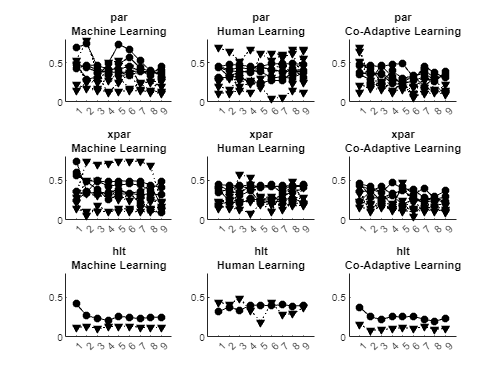

tlo = tiledlayout('flow');
ax_handle_list = [];
for cond = ["par", "xpar", "hlt"]
    y_cond = y_between(y_between.b_condition==cond,2:end);
    for task = ["Machine Learning", "Human Learning", "Co-Adaptive Learning"]
        y_coact = y_cond(:, and(y_within.w_task == task, y_within.w_gesture == "Co-Activation"));
        y_diffact = y_cond(:, and(y_within.w_task == task, y_within.w_gesture == "Differentiation"));
        ax_handle = nexttile;
        ax_handle_list = [ax_handle_list, ax_handle];
        hold on
        plot(y_coact{:,:}', '-ok', 'MarkerFaceColor','k')
        plot(y_diffact{:,:}', ':vk', 'MarkerFaceColor','k')
        hold off
        title([cond, task])
        xticks(1:9)
    end
end
linkaxes(ax_handle_list, 'xy')
ylim([0, 0.8])
xlim([0 10])

tlo = tiledlayout('flow');
ax = nexttile;
x = (1:9)';
y = y_coact{:,:}';
plot_bounded_fit(x,y,ax, "#D2292D")
y = y_diffact{:,:}';
plot_bounded_fit(x,y,ax, "#181818")
fit([x,x], [])

rm = fitrm(y_between, 'y_task1-y_task54~b_condition', "WithinDesign",y_within)

ranova(rm, "WithinModel", "w_task + w_trial + w_gesture + w_trial*w_gesture + w_trial*w_task")

### Individual Data Plotter

task_label = "hl";
input_ttbl = participant_array(2).cond_dict("par").task_dict{task_label}.data_ttbl;
for t = 1:9
    trial_label = sprintf("Trial %02d", t)
    trial_ttbl = extract_segment(input_ttbl, trial_label, task_label);
    trmse_coact = compute_gesture_metric(trial_ttbl, "trmse", "Co-Activation");
    trmse_diffact = compute_gesture_metric(trial_ttbl, "trmse", "Differentiation");
    figure
    title(trial_label)
    subtitle(sprintf("Co-Activation:%.3f\t Differentiation:%.3f", trmse_coact, trmse_diffact))
    hold on
    plot(trial_ttbl.Time, trial_ttbl.("Targets"))
    plot(trial_ttbl.Time, trial_ttbl.("Kalman"))
    hold off
    box off
end

`compute_gesture_metric()`

function weighted_metric = compute_gesture_metric(input_ttbl, metric_type, gesture_name)
gesture_rows = input_ttbl.("Gesture") == gesture_name;
kin_des = input_ttbl{gesture_rows, "Targets"};
kin_pred = input_ttbl{gesture_rows, "Kalman"};
if metric_type == "trmse"
    target_radius = 0.10;
    metric_vals = frm_danly_utils.compute_trmse(kin_des, kin_pred, target_radius);
    weighted_metric = mean( [mean(metric_vals(1:3)), mean(metric_vals(4:5))]);
end
end
% diffact_rows = segmented_ttbl.("Gesture") == "Differentiation";
% segmented_ttbl

`segment_data`

function [segmented_ttbl] = extract_segment(input_ttbl, segmentation_value, task_type)
kalman_variable = "Kalman";
if (task_type == "ml")
    kalman_variable = join(["Kalman",  regexp(segmentation_value, "(\d{2})", 'match')]);
    segmentation_value = "Trial 09";
end
segmented_rows = input_ttbl.("Trial") == segmentation_value;
segmented_ttbl = input_ttbl(segmented_rows, ["Gesture", "Targets", kalman_variable]);
if (task_type == "ml")
    segmented_ttbl = renamevars(segmented_ttbl, kalman_variable, "Kalman");
end
end

plot_bounds

function [fig_handle] = plot_bounded_fit(x, y, ax_handle, y_color)
y_fit = fit(x, y, 'poly1');
y_bounds = predint(y_fit, x, 0.95, 'functional', 'on');
x_conf = [x' flip(x')];
y_conf = [y_bounds(:,2)' flip(y_bounds(:,1)')];
hold on
rgb_color = convertStringsToChars(y_color);
rgb_color = reshape(sscanf(rgb_color(2:end), '%2x') / 255, [], 3);
p = fill(ax_handle, x_conf, y_conf, rgb_color);
p.FaceColor = [rgb_color];
p.FaceAlpha = 0.5;
p.EdgeColor = 'none';
plot(ax_handle, x, y_bounds, '--', 'Color',y_color); xlim ([0 10]); ylim([0 0.8]);
plot(ax_handle, x, [y, feval(y_fit, x)], 'Color', y_color);
hold off
end

function y_task = compute_y_task(y_metric_all_trials, computation_mode)
trials = (1:size(y_metric_all_trials,1))';
switch computation_mode
    case "learning effect"
        y_task = y_metric_all_trials(6:9,:) - y_metric_all_trials(1:4,:); %final - initial
        y_task = [y_task(:,1)', y_task(:,2)']; % coact x4 then diffact x4
    case "exponential learning rate"
        for l=1:size(y_metric_all_trials,2)
            exp_model{l} = fit(trials, y_metric_all_trials(:, l), 'exp1', 'StartPoint', [0.6, -0.2]); % Initial guess from x=1,9;y = 0.5,0.1
            exp_coeffs(l,:) = coeffvalues(exp_model{l});
        end
        y_task = [exp_coeffs(1,2), exp_coeffs(2,2)];
    case "linear learning rate"
        for l=1:size(y_metric_all_trials,2)
            lin_model{l} = fit(trials, y_metric_all_trials(:, l), 'poly1');
            lin_coeffs(l,:) = coeffvalues(lin_model{l});
        end
        y_task = [lin_coeffs(1,1), lin_coeffs(2,1)];
    otherwise
        y_task = [y_metric_all_trials(:,1)', y_metric_all_trials(:,2)'];
end
end